# Powertrain simulation

## Output power initialization

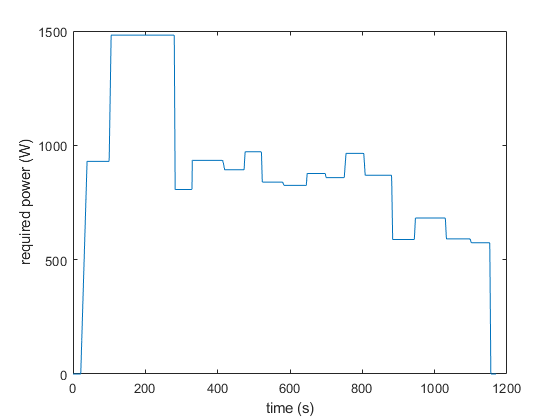

restoredefaultpath;
currentpath = pwd;
currentfolder = strsplit(currentpath,filesep);
while ((~strcmp(currentfolder{end}, 'EMS-aircraft')) && ...
        (~strcmp(currentfolder{end}, 'EMS-aircraft-main')) && ...
        ~isempty(currentfolder{end}))
currentpath = fileparts(currentpath);
currentfolder = strsplit(currentpath,filesep);
end
projectpath = currentpath;
addpath(genpath(projectpath));
clear projectpath currentpath currentfolder
Ts = 1e-3;

%% mid flight ( = 1000)
load load_to_test_for_final_mid
old_w = str2double(to_try.power)';
old_t = str2double(to_try.time)';
t = 0:1e-3:old_t(end);
w = fixpt_interp1(old_t,old_w,t,float('single'),[],float('single'),[],'Floor');
% w = awgn(w,50,'measured');
clear old_w old_t to_try
plot(t,w)
xlabel('time (s)');
ylabel('required power (W)');


% % load to test for final = 400
% load load_to_test_for_final
% old_w = str2double(to_try.power)';
% old_t = str2double(to_try.time)'/2;
% t = 0:1e-3:old_t(end);
% w = fixpt_interp1(old_t,old_w,t,float('single'),[],float('single'),[],'Floor');
% % w = awgn(w,50,'measured');
% plot(t,w)
% xlabel('time (s)');
% ylabel('required power (W)');

% % load_to_test_2 = 3714*2
% load load_to_test_2
% old_w = str2double(to_try.power)';
% old_t = str2double(to_try.time)'/2;
% t = 0:1e-3:old_t(end);
% w = fixpt_interp1(old_t,old_w,t,float('single'),[],float('single'),[],'Floor');



% % load to test descend
% load load_takeoff
% old_w = str2double(to_try.power)';
% old_t = str2double(to_try.time)';
% t = 0:1e-3:old_t(end);
% w = fixpt_interp1(old_t,old_w,t,float('single'),[],float('single'),[],'Floor');
% % w = awgn(w,50,'measured');
% clear old_w old_t to_try
% plot(t,w)
% xlabel('time (s)');
% ylabel('required power (W)');

clear old_w old_t to_try XTest YTest RESTOREDEFAULTPATH_EXECUTED

## Test sources model vs simple resistance

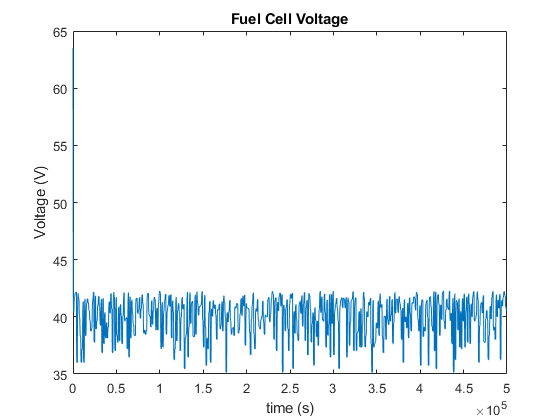

Ts = 1e-3; % Sample time
[BATTdata,FCdata,PVdata,SCdata] = init_sources(Ts,80); % init data sources % SOC set at 80
SimTime = 500; % Max simulation time
Ifc = 0.001;
Ibatt = 0;
Res = 6.09;
Res_batt = 2;
power_fc = zeros(1,SimTime/Ts);
current_fc = zeros(1,SimTime/Ts);
voltage_fc = zeros(1,SimTime/Ts);
power_batt = zeros(1,SimTime/Ts);
current_batt = zeros(1,SimTime/Ts);
voltage_batt = zeros(1,SimTime/Ts);
soc_batt = zeros(1,SimTime/Ts);
time_vector = 0:1:SimTime/Ts-1;
for i=1:1:SimTime/Ts
    %     sprintf("sample : %.0f", i/Ts)
    
    % part sim model
    [FCdata] = fuel_cell_model(Ifc,FCdata);
    [BATTdata] = battery_model(Ibatt,BATTdata);
    
    %     if i == 5
    %         Res = 100;
    %     end
    %     Res = i*Ts+1413*Ts;
    %     if i*Ts > 30
    %         Res = randi(100);
    %     end
    if ~mod(i*Ts,1)
        Res = 1.313 + randi(100)/10;
    end
    
    
    
    %% fc
    % current
    Ifc = FCdata.Efc/Res;
    
    % arrays
    voltage_fc(i) = FCdata.Efc;
    current_fc(i) = Ifc;
    power_fc(i) = Ifc*FCdata.Efc;
    
    if ~mod(i*Ts,1)
        Res_batt = max(2,Res);
        if randi(2) == 1
            Res_batt = -randi(25)/5- 20;
        end
    end
    
    %% batt
    % current
    Ibatt = BATTdata.voltage/(BATTdata.R+Res_batt);
    BATTdata.ouput_voltage = BATTdata.voltage*Res_batt/(BATTdata.R+Res_batt);
    
    % arrays
    voltage_batt(i) = BATTdata.ouput_voltage;
    current_batt(i) = Ibatt;
    power_batt(i) = abs(BATTdata.ouput_voltage)*Ibatt;
    soc_batt(i) = BATTdata.SOC;
end

new_plot(time_vector,voltage_fc,'Fuel Cell Voltage', 'time (s)', 'Voltage (V)')

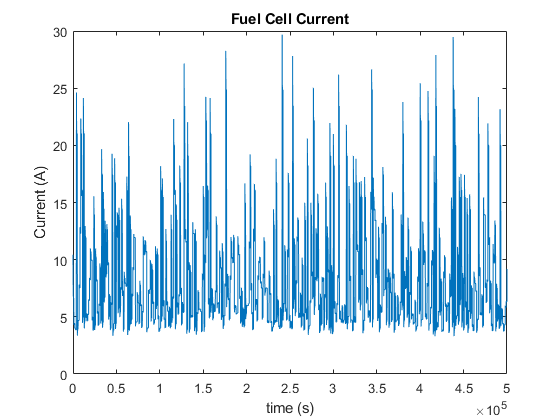

new_plot(time_vector,current_fc,'Fuel Cell Current', 'time (s)', 'Current (A)')

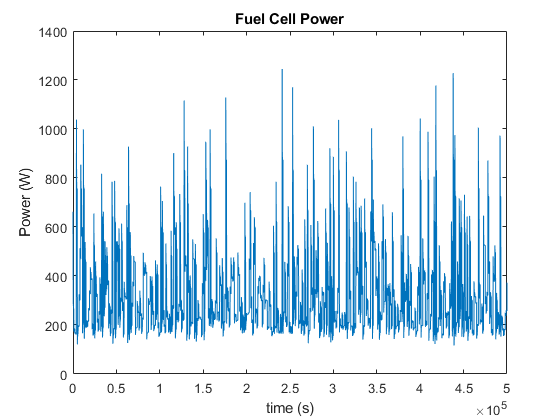

new_plot(time_vector,power_fc,'Fuel Cell Power', 'time (s)', 'Power (W)')

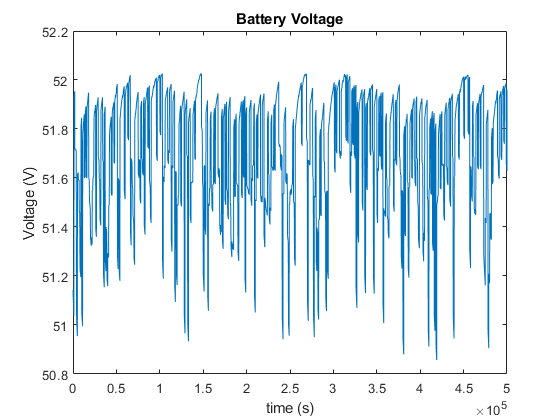


new_plot(time_vector,voltage_batt,'Battery Voltage', 'time (s)', 'Voltage (V)')

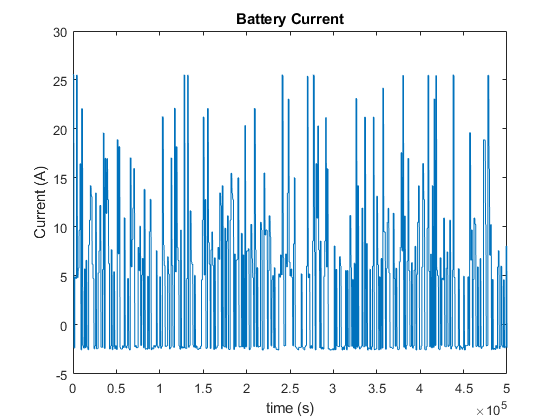

new_plot(time_vector,current_batt,'Battery Current', 'time (s)', 'Current (A)')

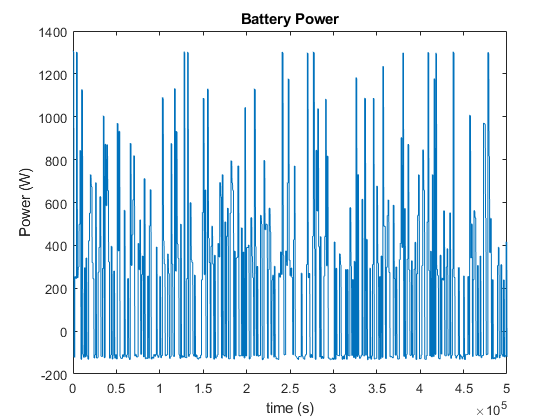

new_plot(time_vector,power_batt,'Battery Power', 'time (s)', 'Power (W)')

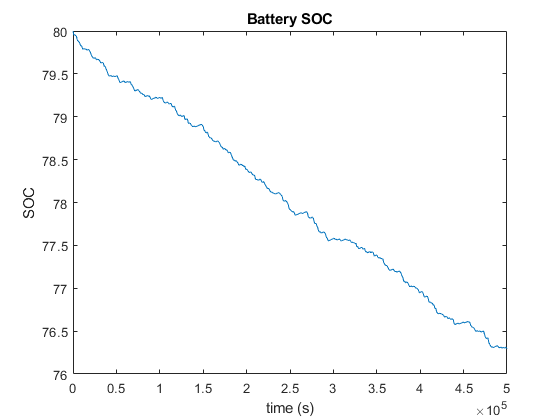

new_plot(time_vector,soc_batt,'Battery SOC', 'time (s)', 'SOC')


mdl_ifc = fitlm(power_fc,current_fc); % current depending on the power(t)
X = [power_batt(1:1:end); soc_batt(1:1:end)]';
mdl_ibatt = fitlm(X,current_batt(1:1:end)); % current depending on soc(t) and power(t)
% feval(mdl_ibatt,power_batt(1:1:end),soc_batt(1:1:end)); % to use
mdl_dsoc = fitlm(power_batt(1:end-1),diff(soc_batt));
[80+feval(mdl_dsoc,power_batt(1)) soc_batt(2) (80+feval(mdl_dsoc,power_batt(1)))/soc_batt(2)]

ans =   79.999952781048862  79.999952646468259   1.000000001682259


% save('mdl_dsoc','mdl_dsoc');
% save('mdl_ibatt','mdl_ibatt');
% save('mdl_ifc','mdl_ifc');

### Dynamic Programming Backward

Ts = 1; % Sample time
[BATTdata,FCdata,PVdata,SCdata] = init_sources(Ts,80); % init data sources % SOC set at 80
SimTime = t(end); % Max simulation time
power_fc_dp = zeros(1,SimTime/Ts);
power_batt_dp = zeros(1,SimTime/Ts);
soc_batt_dp = zeros(1,SimTime/Ts);
dsoc_dp = feval(mdl_dsoc,-200:0.01:1200);
soc_0 = soc_batt(1);
soc_f = soc_batt(end);
soc = 20:1:90;
max_soc = 90;
min_soc = 20;
time_vector = 0:Ts:SimTime-Ts;
dPfc = 100;
Pfc_max = 1100;
Pfc_min = 0;
Ppv_out = 145*0.9;
% Pout = w(610e3+1:Ts/1e-3:630/1e-3);
Pout = w(1:Ts/1e-3:SimTime/1e-3);
fc_power_array = zeros(length(soc),SimTime/Ts);
fc_power_array(:,end)=min(Pfc_max,max(Pfc_min,Pout(end)));
Pbatt_max = 1000;
Pbatt_min = -200;
global_cost = zeros(length(soc),SimTime/Ts);
batt_power_array = zeros(length(soc),SimTime/Ts);
old_fc_func = zeros(length(soc),SimTime/Ts);
old_batt_func = zeros(length(soc),SimTime/Ts);
old_h2_func = zeros(length(soc),SimTime/Ts);
tStart = tic;
tic
for i=SimTime/Ts-1:-1:1
    for j=1:length(soc)
        Pout_required = Pout(i)-Ppv_out;
        
        %         % old
        %         ubPfc = min([Pfc_max]);
        %         lbPfc = max([Pfc_min]);
        %         Pfc_grid = linspace(lbPfc,ubPfc,101); % fuel cell power grid
        %         Pbatt_grid = Pout_required/0.9 - Pfc_grid;
        %         Pbatt_grid = min(1000,max(-200,Pbatt_grid));
        %
        %         dsoc_grid = 1e3/Ts*feval(mdl_dsoc,Pbatt_grid); % delta soc grid (possible)
        %         soc_grid = soc(j) - dsoc_grid; % next soc possible
        %         next_soc_index = closest_value(soc,soc_grid); % next soc possible
        %         next_Pfc = fc_power_array(next_soc_index,i+1)';
        %
        %         Ifc_in = feval(mdl_ifc,Pfc_grid); % function of Pfc
        %         Ibatt_in = feval(mdl_ibatt,Pbatt_grid,soc_grid); % function of Pbatt and SOC
        %
        %         [gcf,new_fc_func,new_batt_func,new_h2_func] = one_global_cost_function(0,SimTime/Ts-i,...
        %             Pfc_grid,Ifc_in,Ibatt_in,soc_grid,old_fc_func(j,i+1),old_batt_func(j,i+1),...
        %             old_h2_func(j,i+1),SimTime/Ts-i);  % global cost function calculation for all the different soc
        %
        %         %         lcf = 0;
        %         lcf = local_cost_function_2(Pfc_grid,soc_grid,zeros(1,length(soc_grid))+soc(j),next_Pfc);
        %
        %         [global_cost(j,i), k] = min([gcf + lcf]);
        %         batt_power_array(j,i) = Pbatt_grid(k);
        %         fc_power_array(j,i) = Pfc_grid(k);
        %         old_fc_func(j,i) = old_fc_func(j,i+1) + new_fc_func(k);
        %         old_batt_func(j,i) = old_batt_func(j,i+1) + new_batt_func(k);
        %         old_h2_func(j,i) = old_h2_func(j,i+1) + new_h2_func(k);
        
        % new
        Pbatt_grid = linspace(-200,1000,141);
        
        dsoc_grid = 1e3/Ts*feval(mdl_dsoc,Pbatt_grid); % delta soc grid (possible)
        soc_grid = soc(j) + dsoc_grid;
        ind_range = find(soc_grid<min_soc | soc_grid>max_soc); % del soc / Pbatt not in range
        soc_grid(ind_range) = [];
        Pbatt_grid(ind_range) = [];
        
        next_soc_index = closest_value(soc,soc_grid); % next soc possible
        next_Pfc = fc_power_array(next_soc_index,i+1)'; % next pfc based on soc possible
        ubPfc = min(zeros(1,length(next_Pfc))+Pfc_max, next_Pfc+dPfc); % upper
        lbPfc = max(zeros(1,length(next_Pfc))+Pfc_min, next_Pfc-dPfc); % lower bound for PFC
        Pfc_grid = min(ubPfc,max(lbPfc,(Pout_required/0.9-Pbatt_grid))); % Pfc grid based on next value and soc
        Pbatt_grid = Pout_required/0.9-Pfc_grid; % rearrange Pbatt
        
        
        Ifc_in = feval(mdl_ifc,Pfc_grid); % function of Pfc
        Ibatt_in = feval(mdl_ibatt,Pbatt_grid,soc_grid); % function of Pbatt and SOC
        
        [gcf,new_fc_func,new_batt_func,new_h2_func] = one_global_cost_function(0,SimTime/Ts-i,...
            Pfc_grid,Ifc_in,Ibatt_in,soc_grid,old_fc_func(next_soc_index,i+1)',old_batt_func(next_soc_index,i+1)',...
            old_h2_func(next_soc_index,i+1)',SimTime/Ts-i);  % global cost function calculation for all the different soc
        
        %                 lcf = 0;
        %         lcf = local_cost_function(Pfc_grid,soc_grid,Pbatt_grid,Ts);
        lcf = local_cost_function_2(Pfc_grid,soc_grid,zeros(1,length(soc_grid))+soc(j),next_Pfc);
        
        [global_cost(j,i), k] = min([gcf + lcf]);
        batt_power_array(j,i) = Pbatt_grid(k);
        fc_power_array(j,i) = Pfc_grid(k);
        old_fc_func(j,i) = old_fc_func(next_soc_index(k),i+1) + new_fc_func(k);
        old_batt_func(j,i) = old_batt_func(next_soc_index(k),i+1) + new_batt_func(k);
        old_h2_func(j,i) = old_h2_func(next_soc_index(k),i+1) + new_h2_func(k);
    end
    if ~mod(i,100)
        toc
        sprintf("sample : %.0f", i)
        tic
    end
end

Elapsed time is 24.369432 seconds.


ans = "sample : 400"

Elapsed time is 74.788201 seconds.


ans = "sample : 300"

Elapsed time is 78.062581 seconds.


ans = "sample : 200"

Elapsed time is 78.500845 seconds.


ans = "sample : 100"

toc

Elapsed time is 78.726957 seconds.


toc(tStart)

Elapsed time is 335.126297 seconds.


#### Test DP

Ts = 1e-1  ; % Sample time
[BATTdata,FCdata,PVdata,SCdata] = init_sources(Ts,75); % init data sources % SOC set at 80
% SimTime = t(end); % Max simulation time
Vdc_wanted = 72;
Ifc = 0.001;
Ibatt = 0;
Res_fc = w(1);
Res_batt = w(1);
power_fc = zeros(1,SimTime/Ts);
current_fc = zeros(1,SimTime/Ts);
voltage_fc = zeros(1,SimTime/Ts);
power_batt = zeros(1,SimTime/Ts);
current_batt = zeros(1,SimTime/Ts);
voltage_batt = zeros(1,SimTime/Ts);
soc_batt = zeros(1,SimTime/Ts);
test = zeros(1,SimTime/Ts);
Pfc = 0;
Ppv_out = 145*0.9;
Pout = w(1:Ts/1e-3:SimTime/1e-3);
% Pout = w(610e3+1:Ts/1e-3:630/1e-3);
time_vector = 0:Ts:SimTime-Ts;
% old_EFC = FCdata.Efc;
tic
for i=1:1:SimTime/Ts
    %         sprintf("sample : %.0f", i/Ts)
    [BATTdata] = battery_model(Ibatt,BATTdata);
    [FCdata] = fuel_cell_model(Ifc,FCdata);
    
    Pout_required = Pout(i)-Ppv_out;
    if i>1 && ~mod(i,1/Ts)
        [value,index] = min(abs(soc-BATTdata.SOC));
        Pfc = max(0,min(1100,fc_power_array(index,i*Ts)));
%         Pbatt = max(-200,min(1000,batt_power_array(index,i/1e3)));
%         Pfc = Pout_required/0.9 - Pbatt;
% Ifc
% Pfc
% FCdata.E_act
%         FCdata.old_E_act_bl
%         FCdata.old_E_act_d
%         FCdata.Efc
    end
    Pbatt = Pout_required/0.9 - Pfc;
    
    Ifc = Pfc/FCdata.Efc;

    
    % arrays
    voltage_fc(i) = FCdata.Efc;
    current_fc(i) = Ifc;
    power_fc(i) = Ifc*FCdata.Efc;
    
    
    %% batt
    Res_batt = (BATTdata.voltage ^2)/Pbatt-BATTdata.R;
    
    % current
    Ibatt = BATTdata.voltage/(BATTdata.R+Res_batt);
    BATTdata.ouput_voltage = BATTdata.voltage*Res_batt/(BATTdata.R+Res_batt);
    
    % arrays
    voltage_batt(i) = BATTdata.ouput_voltage;
    current_batt(i) = Ibatt;
    power_batt(i) = BATTdata.ouput_voltage*Ibatt;
    soc_batt(i) = BATTdata.SOC;
end
toc

Elapsed time is 0.275950 seconds.


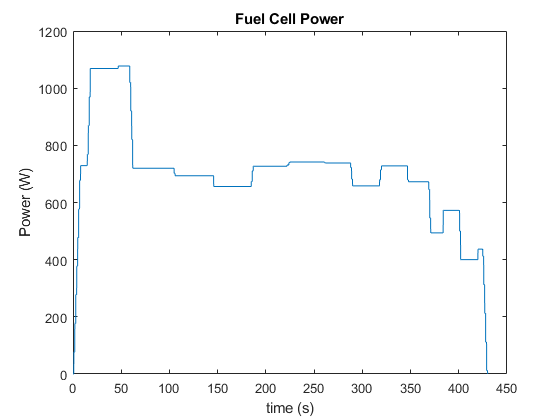

new_plot(time_vector,power_fc,'Fuel Cell Power', 'time (s)', 'Power (W)')

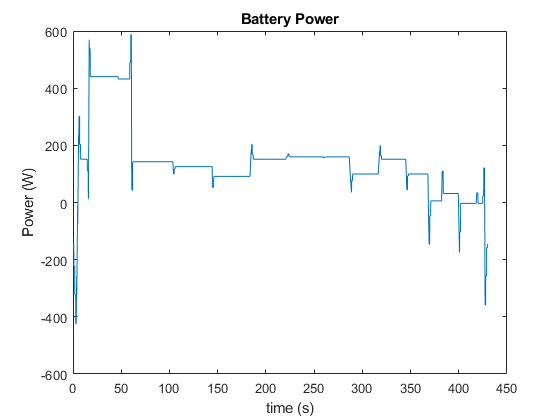

new_plot(time_vector,power_batt,'Battery Power', 'time (s)', 'Power (W)')

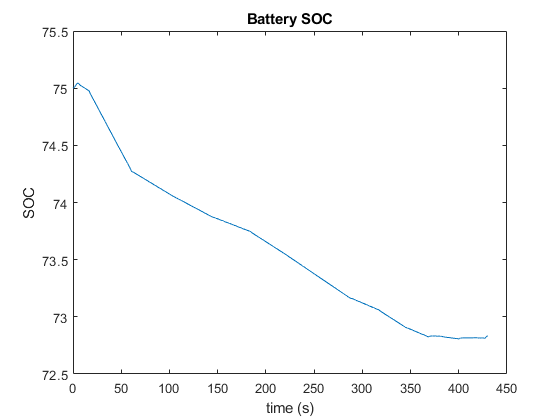

new_plot(time_vector,soc_batt,'Battery SOC', 'time (s)', 'SOC')

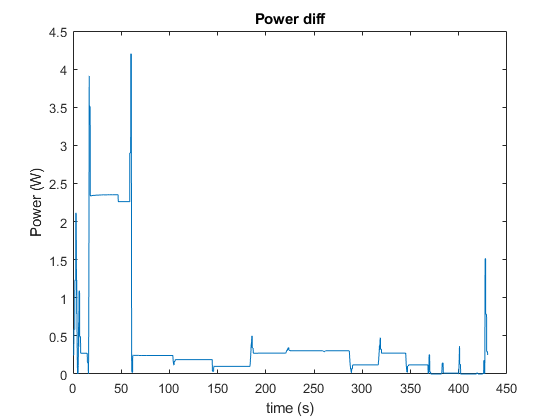

new_plot(time_vector,(Pout-Ppv_out)/0.9-(power_batt+power_fc),'Power diff', 'time (s)', 'Power (W)');


sum(local_cost_function(power_fc,soc_batt,power_batt,Ts)) % 1.5532e6

ans =      3.570219699036777e+05


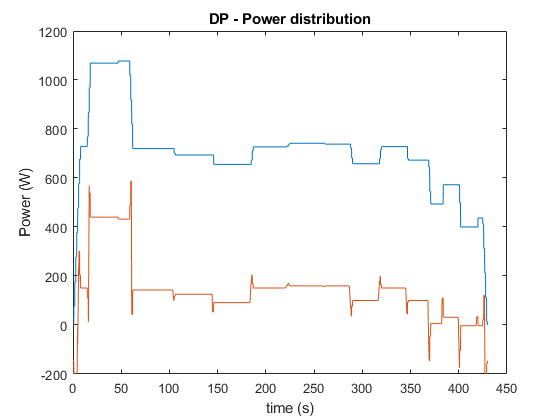

plot(time_vector,power_fc)
hold on
plot(time_vector,power_batt)
ylim([-200 1200])
title('DP - Power distribution')
xlabel('time (s)')
ylabel('Power (W)')
hold off


global_cost_funciton(power_fc,current_fc,current_batt,soc_batt,time_vector) % without DeltaPfc 397.9367 % with 308.4196 % complete 1.3557e3 % % complete x 2  = 1.359e3

ans =   76.372403806274278


soc_batt(end)

ans =   72.835767412159413


mean(power_fc)

ans =      7.015473842346303e+02


mean(power_batt)

ans =      1.402831804148888e+02



% h = surf(0:1169,20:90,fc_power_array)
% set(h,'LineStyle','none')
ssss = size(fc_power_array);
h = surf(0:ssss(2)-1,20:1:90,fc_power_array)

h =   Surface with properties:

       EdgeColor: [0 0 0]
       LineStyle: '-'
       FaceColor: 'flat'
    FaceLighting: 'flat'
       FaceAlpha: 1
           XData: [1×430 double]
           YData: [20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 65 66 67 68 69 70 71 72 73 74 75 76 77 78 79 80 81 82 83 84 85 86 87 88 89 90]
           ZData: [71×430 double]
           CData: [71×430 double]

  Show all properties


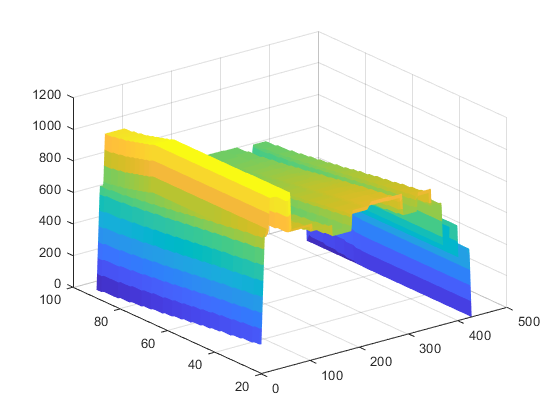

set(h,'LineStyle','none')

% 360 in real